teaminfo = readtable('C:\class\coursefiles\mlbe\epl\EPLteams.xlsx')

teaminfo =              Team             Payroll_M__            Manager            ManagerHireDate    ManagerNationality
    ______________________    ___________    _______________________    _______________    __________________

    'Arsenal'                   192          'Arsène Wenger'            10/1/1996          'France'          
    'Aston Villa'              65.1          'Eric Black'               3/29/2016          'Scotland'        
    'Bournemouth'                25          'Eddie Howe'               10/12/2012         'England'         
    'Chelsea'                 215.6          'Guus Hiddink'             12/19/2015         'Netherlands'     
    'Crystal Palace'           54.3          'Alan Pardew'              1/2/2015           'England'         
    'Everton'                  74.7          'Da


teaminfo.Properties.VariableDescriptions

ans =     ''    'Original column heading: 'Payroll (M£)''    ''    'Original column heading: 'Manager Hire Date''    'Original column heading: 'Manager Nationality''


teaminfo.Properties.VariableNames{2} = 'Payroll'

teaminfo =              Team             Payroll            Manager            ManagerHireDate    ManagerNationality
    ______________________    _______    _______________________    _______________    __________________

    'Arsenal'                   192      'Arsène Wenger'            10/1/1996          'France'          
    'Aston Villa'              65.1      'Eric Black'               3/29/2016          'Scotland'        
    'Bournemouth'                25      'Eddie Howe'               10/12/2012         'England'         
    'Chelsea'                 215.6      'Guus Hiddink'             12/19/2015         'Netherlands'     
    'Crystal Palace'           54.3      'Alan Pardew'              1/2/2015           'England'         
    'Everton'                  74.7      'David Unsworth'           5/12/201

teaminfo.Properties.Description = 'Info on football teams in 2015-2016 EPL'

teaminfo =              Team             Payroll            Manager            ManagerHireDate    ManagerNationality
    ______________________    _______    _______________________    _______________    __________________

    'Arsenal'                   192      'Arsène Wenger'            10/1/1996          'France'          
    'Aston Villa'              65.1      'Eric Black'               3/29/2016          'Scotland'        
    'Bournemouth'                25      'Eddie Howe'               10/12/2012         'England'         
    'Chelsea'                 215.6      'Guus Hiddink'             12/19/2015         'Netherlands'     
    'Crystal Palace'           54.3      'Alan Pardew'              1/2/2015           'England'         
    'Everton'                  74.7      'David Unsworth'           5/12/201


teaminfo.Properties

ans =              Description: 'Info on football teams in 2015-2016 EPL'
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Team'  'Payroll'  'Manager'  'ManagerHireDate'  'ManagerNationality'}
    VariableDescriptions: {''  'Original column heading: 'Payroll (M£)''  ''  'Original column heading: 'Manager Hire Date''  'Original column heading: 'Manager Nationality''}
           VariableUnits: {}
                RowNames: {}


mgmt = teaminfo.Manager

mgmt =     'Arsène Wenger'
    'Eric Black'
    'Eddie Howe'
    'Guus Hiddink'
    'Alan Pardew'
    'David Unsworth'
    'Claudio Ranieri'
    'Jürgen Klopp'
    'Manuel Pellegrini'
    'Louis van Gaal'
    'Rafael Benítez'
    'Alex Neil'
    'Ronald Koeman'
    'Mark Hughes'
    'Sam Allardyce'
    'Francesco Guidolin'
    'Mauricio Pochettino'
    'Quique Sánchez Flores'
    'Tony Pulis'
    'Slaven Bilić'



m4 = mgmt(4)    % m4 is a cell array

m4 =     'Guus Hiddink'


m4 = mgmt{4}    % m4 is a character array

m4 = Guus Hiddink


mgmt{4} = 'Antonio Conte'

mgmt =     'Arsène Wenger'
    'Eric Black'
    'Eddie Howe'
    'Antonio Conte'
    'Alan Pardew'
    'David Unsworth'
    'Claudio Ranieri'
    'Jürgen Klopp'
    'Manuel Pellegrini'
    'Louis van Gaal'
    'Rafael Benítez'
    'Alex Neil'
    'Ronald Koeman'
    'Mark Hughes'
    'Sam Allardyce'
    'Francesco Guidolin'
    'Mauricio Pochettino'
    'Quique Sánchez Flores'
    'Tony Pulis'
    'Slaven Bilić'



teaminfo.Manager = mgmt

teaminfo =              Team             Payroll            Manager            ManagerHireDate    ManagerNationality
    ______________________    _______    _______________________    _______________    __________________

    'Arsenal'                   192      'Arsène Wenger'            10/1/1996          'France'          
    'Aston Villa'              65.1      'Eric Black'               3/29/2016          'Scotland'        
    'Bournemouth'                25      'Eddie Howe'               10/12/2012         'England'         
    'Chelsea'                 215.6      'Antonio Conte'            12/19/2015         'Netherlands'     
    'Crystal Palace'           54.3      'Alan Pardew'              1/2/2015           'England'         
    'Everton'                  74.7      'David Unsworth'           5/12/201

m4 = teaminfo.Manager{4}

m4 = Antonio Conte

teaminfo.Manager{4} = 'Antonio Conte'

load 'C:\class\coursefiles\mlbe\epl\EPLresults.mat'

EPLJ = join(teaminfo,EPL,'Keys','Team')

EPLJ =              Team             Payroll            Manager            ManagerHireDate    ManagerNationality    HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD 
    ______________________    _______    _______________________    _______________    __________________    ________    _________    __________    ______    ______    ________    _________    __________    ______    

% innerjoin (like join, intersection)
% outerjoin (union)

MHD = EPLJ.ManagerHireDate

MHD =    10/1/1996 
   3/29/2016 
   10/12/2012
   12/19/2015
   1/2/2015  
   5/12/2016 
   7/13/2015 
   10/8/2015 
   6/14/2013 
   7/14/2014 
   3/11/2016 
   1/9/2015  
   6/16/2014 
   5/30/2013 
   10/9/2015 
   1/18/2016 
   5/27/2014 
   6/5/2015  
   1/1/2015  
   6/9/2015  


% table on page 8-9

tp = datetime('now')

tp =    10-Jan-2017 15:26:26


tb = datetime('11/05/10','InputFormat','MM/dd/yy')

tb =    05-Nov-2010


dt = tp - tb

dt =    54207:26:26


days(dt)

ans = 2.2586e+03

dtC = between(tb,tp)

dtC =    6y 2mo 5d 15h 26m 26.303s



seasonStart = datetime(2015,8,8)

seasonStart =    08-Aug-2015


seasonStart.Format = 'ee dd/MM/yy G'

seasonStart =    07 08/08/15 CE



mgrTenure = days(seasonStart - MHD)

mgrTenure =         6885
        -234
        1030
        -133
         218
        -278
          26
         -61
         785
         390



EPLJ.mgrTenure = mgrTenure

EPLJ =              Team             Payroll            Manager            ManagerHireDate    ManagerNationality    HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA    Points    GD     mgrTenure
    ______________________    _______    _______________________    _______________    __________________    ________    _________    __________    ______    ______    ________    _________    __________    

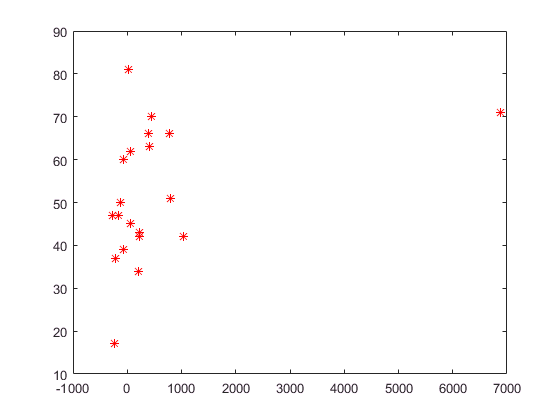

plot(EPLJ.mgrTenure, EPLJ.Points, 'r*')

xlim([-1000 2000])

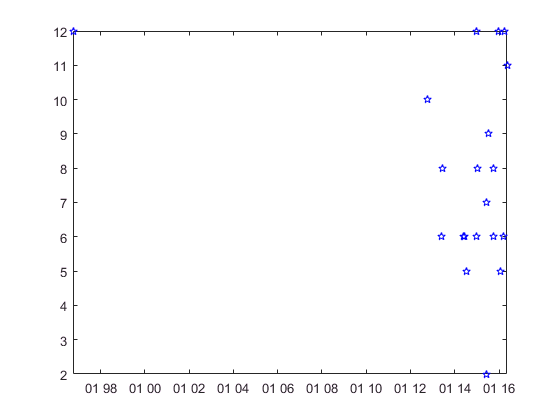

plot(EPLJ.ManagerHireDate,EPL.HomeWins,'bp','DatetimeTickFormat', ...
    'QQ yy')

datetick('x','QQ yy','keepticks')
